# MetaboAnnotator: An efficient toolbox to annotate metabolites in genome-scale metabolic reconstructions

Tutorial is still being developed, and may be incomplete or contain minor errors. IT 24.11.2021.

## Author(s): Ines Thiele, National University of Ireland, Galway, Ireland.

## Reviewer(s): 

## INTRODUCTION

The purpose of this COBRA toolbox extension, MetaboAnnotator, is to annotate metabolites comprehensively with database independent and dependent identifiers (IDs). Genome-scale metabolic reconstructions have been assembled for thousands of organisms using a wide-range of tools. However, metabolite annotations, required to compare and link metabolites between reconstructions remain incomplete. Here, we aim to further extend the annotation coverage using various databases and chemoinformatic approaches.

MetaboAnnotator comprehensively annotates input metabolites with database independent and dependent identifiers, obtains mol files, and calculates metabolite formula and charge at pH 7.2. The resulting metabolite annotations allow for subsequent cross mapping between reconstructions and mapping of, e.g., metabolomic data. 

The overall approach of MetaboAnnotator is depicted here:

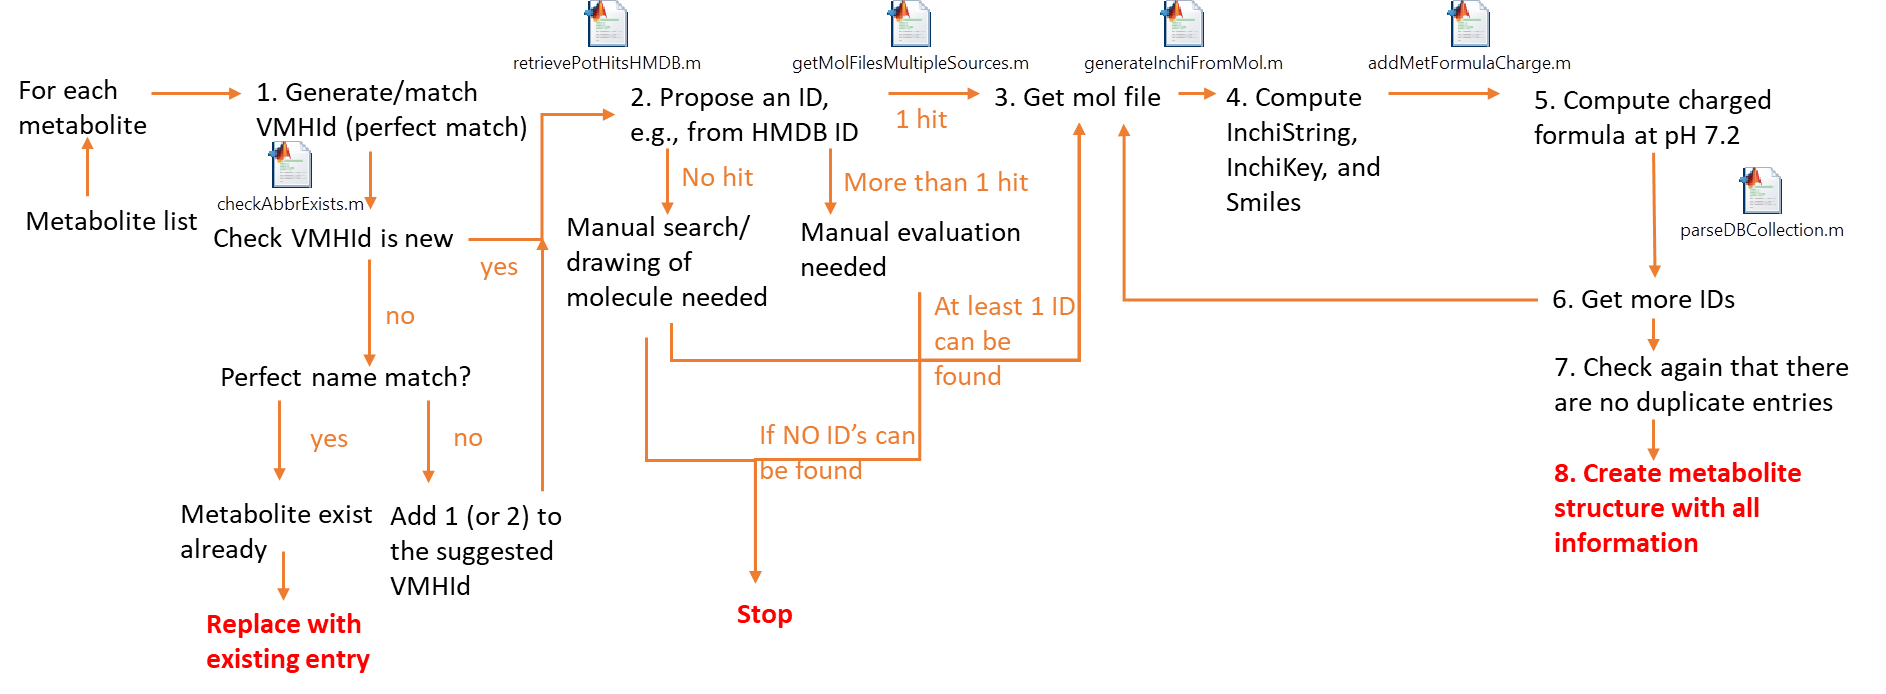

In total, up to 72 different database dependent and independent IDs are collected. Importantly, each retrieved ID is associated with the source, an annotation stamp (e.g., automatic), and date, for tractability.

# Prerequisits

- Matlab v2020b and above (lower versions have not been tested).

- Working COBRA toolbox v3: [https://github.com/opencobra/cobratoolbox](https://github.com/opencobra/cobratoolbox) 

- openBabel: [http://openbabel.org/wiki/Main_Page](http://openbabel.org/wiki/Main_Page) 

- ChemAxon: [https://chemaxon.com/](https://chemaxon.com/) (free academic license can be requested)

- Collection of mol files, provided in the COBRA toolbox v3. This needs to be checked out separately. See next step

Obtain the collection of mol files by checking out the following git repo. This needs to be done only ones (time consuming).

url='https://github.com/opencobra/ctf/archive/refs/heads/main.zip';
websave([directory  ],url);

translation = 19×2 cell array
    {'fullName'      }    {'metNames'                     }
    {'chargedFormula'}    {'metFormulas'                  }
    {'charge'        }    {'metCharges'                   }
    {'keggId'        }    {'metKEGGID'                    }
    {'inchiKey'      }    {'metisinchi_keyID'             }
    {'hmdb'          }    {'metHMDBID'                    }
    {'cheBIId'       }    {'metChEBIID'                   }
    {'metanetx'      }    {'metMetaNetXID'                }
    {'seed'          }    {'metSEEDID'                    }
    {'biggId'        }    {'metBiGGID'                    }
    {'biocyc'        }    {'metBioCycID'                  }
    {'reactome'      }    {'metisreactome__46__compoundID'}
    {'lipidmaps'     }    {'metLIPIDMAPSID'               }
    {'sboTerms'      }    {'metSBOTerms'                  }
    {'drugbank'      }    {'metiskegg__46__drugID'        }
    {'sabiorkID'     }    {'metissabiorkID'               }
    {'inch

0.018519Collecting Missing HMDB Mol Form 
The server returned the status 500 with message "Internal Server Error" in response to the request to URL https://hmdb.ca/structures/metabolites/HMDB00122;%20HMDB06564.mol.
The following structures could not be obtained
    {'hmdb - HMDB00122; HMDB06564'}

The server returned the status 500 with message "Internal Server Error" in response to the request to URL https://hmdb.ca/structures/metabolites/HMDB00122;%20HMDB06564.mol.
The following structures could not be obtained
    {'hmdb - HMDB00122; HMDB06564'}

Generate database independent id from mol files 
Elapsed time is 6.740780 seconds.

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54


if strfind('main.zip')
    if ismac

ans = 10×3 table
            ID            Count Before    Count After
    __________________    ____________    ___________

    {'Agora2'        }          0             51     
    {'Agora2_source' }          0             51     
    {'GNPS'          }          0              0     
    {'GNPS_source'   }          0              0     
    {'MoNa'          }          0              0     
    {'MoNa_source'   }          0              0     
    {'Recon3D'       }          0             48     
    {'Recon3D_source'}          0             48     
    {'VMHId'         }         54             52     
    {'VMHId_source'  }        NaN             52     


        system(['zip -d ' directory]);
    elseif ispc
        unzip(directory) % creates a directory called ctf-main
    end

translation = 19×2 cell array
    {'fullName'      }    {'metNames'                     }
    {'chargedFormula'}    {'metFormulas'                  }
    {'charge'        }    {'metCharges'                   }
    {'keggId'        }    {'metKEGGID'                    }
    {'inchiKey'      }    {'metisinchi_keyID'             }
    {'hmdb'          }    {'metHMDBID'                    }
    {'cheBIId'       }    {'metChEBIID'                   }
    {'metanetx'      }    {'metMetaNetXID'                }
    {'seed'          }    {'metSEEDID'                    }
    {'biggId'        }    {'metBiGGID'                    }
    {'biocyc'        }    {'metBioCycID'                  }
    {'reactome'      }    {'metisreactome__46__compoundID'}
    {'lipidmaps'     }    {'metLIPIDMAPSID'               }
    {'sboTerms'      }    {'metSBOTerms'                  }
    {'drugbank'      }    {'metiskegg__46__drugID'        }
    {'sabiorkID'     }    {'metissabiorkID'               }
    {'inch

end

# Case 1. If you are starting with a metabolic reconstruction

A metabolic reconstruction can be used as an input. In this case, a** metabolic reconstruction** is loaded and its metabolites are converted into a metabolite structure. The metabolite abbreviations will be used as field names for the metabolite structure. If metabolite IDs are provided, they will be used to pre-populate the metabolite structure. 

outputFileName = 'collectedMetStructEcore';

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

[metabolite_structureEcore,tableMappingOverview] = model2MetStructure('e_coli_core','SBML',outputFileName);

*metabolite_structureEcore* contains the information for each metabolite in the metabolic reconstruction. 

*tableMappingOverview* compares the number of ID's present in the metabolic reconstruction (as provided in the input file (here: e_coli_core)).

tableMappingOverview(1:10,:)

All data are also saved in a matlab file, named based on *outputFileName*. 

As a final step, we can populate the metabolic reconstruction with the retrieved IDs. Please note that currently only those IDs are added for which fields have been defined in the COBRA toolbox.

model=readCbModel(filename,'fileType',filetype);

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 27

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 50

i = 51

i = 52

i = 53

i = 54

[modelUpdated] = populateModelMetStr(model, metabolite_structureEcore);

# Case 2. If you are starting with a metabolite list in a xlsx file

## 2. a. Load xlsx file and perform quality checks

If VMH Id's are defined in the input file, then the header (1st row) must contain 'vmh' in the corresponding column. Otherwise, the header must contain 'name' in the column for the metabolite name - in this case, unique VMH Id's will be generated.

Define input filename:

  fileName = 'C:\Users\0123322S\Downloads\highFreq_decreasedMets_IT.xlsx';

*VMH_existance* reports for each abbreviation whether it exists as rxn abbr (column 2) or as metabolite abbr (column 3) in the VMH. '0' is absent. '1' is present.

*rBioNet_existance* reports for each abbreviation whether it exists as rxn abbr (column 2) or as metabolite abbr (column 3) in the rBioNet (as found in 'https://raw.githubusercontent.com/opencobra/COBRA.papers/master/2021_demeter/input/'). '0' is absent. '1' is present.

If all new metabolite abbr are new to VMH & rBioNet, no duplicates exist, THEN create metabolite structure from xlsx file. Note that these checks will be done again in *list2MetaboliteStructure*

molDirectory = 'molFiles'; % directory where downloaded mol files should be downloaded.
[metabolite_structure] = list2MetaboliteStructure(fileName,molDirectory);
[IDs,IDcount,Table] = getStatsMetStruct(metabolite_structure);

The *metabolite_structure* contains the information listed in the xlsx file, in accordance with predefined, allowable fields, specified in* metaboliteStructureFieldNames.m*. Each allowable field is accompagnied by a field containing '_source'. Here, the information origin (in this case, the *fileName*) and the current date are added for reproducibility and tractability.

*Table* contains the same information as *metabolite_structure*, only in table format.

*IDs* contains the list of metabolite abbrevation and *IDcount* contains the corresponding information on how many fields (e.g., external database IDs) have been associated with each metabolite abbreviation. The count has been done based on the provided *metabolite_structure*.

# Case 3. If you are starting from a cell array or matlab table containing the metabolite list

**3a. If you have VMH Id's**

First column must contain the (newly formulated) VMH ids. The first row must contain the header naming for each column. Based on the header naming the fields will be attributed to the metabolites in the metabolite_structure.

met={ % Nicotine & Cotidine pathway
     'VMH ID' 'metabolite_name' 'HMDB' 'inchistring' 'neutral_formula' 'charged_formula' 'charge'
    'cot' 'Cotinine' 'HMDB0001046'  '' '' '' ''
    'coto' 'Cotinine n-oxide' 'HMDB0001411'  '' '' '' ''
    'nnct' 'Nornicotine' 'HMDB0001126'  '' '' '' ''
    '2hnct' '2-hydroxynicotine' 'HMDB0001329'   '' '' '' ''
    'ncot' 'Norcotinine' 'HMDB0001297'  '' '' '' ''
    'hmcot' 'N-hydroxymethylnorcotinine' 'HMDB0001324'  '' '' '' ''
    '5hcot' '5-hydroxycotinine' 'HMDB0001427'   '' '' '' ''
    'thcot' 'Trans-hydroxycotinine' 'HMDB0001390'  '' '' '' ''
    'thcotg' 'Trans-3-hydroxycotinine glucuronide' 'HMDB0001204'  '' '' '' ''
    'cotg' 'cotinine glucuronide' 'HMDB0001013' '' '' '' ''
    'nct' 'Nicotine' 'HMDB0001934' '' '' '' ''
    'nctim'  'Nicotine imine' 'HMDB0001010'  '' '' '' ''
    'nctg' 'Nicotine glucuronide' 'HMDB0001272'  '' '' '' ''
    'nct1o' 'Nicotine-1-N-oxide' 'HMDB0001497'  '' '' '' ''
    'ninct' 'N-nitrosonornicotine' 'HMDB0041940'  '' '' '' ''
    'mnct' 'N-methylnicotinium' 'HMDB0001009' '' '' '' ''
    '4hpbuta'  '4-hydroxy-4-(3-pyridyl)-butanoic acid' 'HMDB0001119' '' '' '' ''
    '4opbuta'  '4-oxo-4-(3-pyridyl)butanoic acid' 'HMDB0000992' '' '' '' ''
    '4opmbutam'   '4-oxo-4-(3-pyridyl)-N-methylbutanamide' 'HMDB0001004' '' '' '' ''
    '4opbutam' '4-oxo-4-(3-pyridyl)-butanamide' 'HMDB0001267' '' '' '' ''
    '4mapbutone' '4-(methylamino)-1-(3-pyridyl)-1-butanone' 'HMDB0001240' '' '' '' ''
    'cotmi' 'Cotinine methonium ion' 'HMDB0001365' '' '' '' ''
    '4pbute' '4-(3-pyridyl)-3-butenoic acid' 'HMDB0001424' '' '' '' ''
    '4pbuta' '4-(3-pyridyl)-butanoic acid' 'HMDB0001007' '' '' '' ''
    '3pac' '3-pyridylacetic acid' 'HMDB0001538' '' '' '' ''
    };


Create and populate the metabolite structure for the metabolites given in metList. Note that the function checks whether VMH ID's exist already.

molDirectory = 'molFiles'; % directory where downloaded mol files should be downloaded.
[metabolite_structure] = list2MetaboliteStructure([],molDirectory,metList);
[IDs,IDcount,Table] = getStatsMetStruct(metabolite_structure);

The *metabolite_structure* contains the information listed in the xlsx file, in accordance with predefined, allowable fields, specified in* metaboliteStructureFieldNames.m*. Each allowable field is accompagnied by a field containing '_source'. Here, the information origin (in this case, the *fileName*) and the current date are added for reproducibility and tractability.

*Table* contains the same information as *metabolite_structure*, only in table format.

*IDs* contains the list of metabolite abbrevation and *IDcount* contains the corresponding information on how many fields (e.g., external database IDs) have been associated with each metabolite abbreviation. The count has been done based on the provided *metabolite_structure*.

**3b. If you do not have VMH ID's but only names**

  metList = {'N-Acetyl-5-Aminosalicylic Acid'
      '5-Fluorocytosine'
      '5-Fluorouracil'
      '5-Fluorouridine'
      '5-Fluorouridine Monophosphate'
      'Alpha-Fluoro-Beta-Ureidopropionate'
      'N-Carboxy-Alpha-Fluoro-Beta-Alanine'
      '5,6-Dihydro 5-Fluoro Uracil'
      'Amantadine'
      };
  
  molDirectory = 'molFiles'; % directory where downloaded mol files should be downloaded.
[metabolite_structure] = list2MetaboliteStructure([],molDirectory,metList);

## Overview: Useful tools in the toolbox

- **If you wish to provide a list of VMH abbreviations to check against when creating new metabolite abbreviations:**

  fileName = 'C:\Users\0123322S\Downloads\highFreq_decreasedMets_IT.xlsx';
  molDirectory = 'molFiles'; % directory where downloaded mol files should be downloaded.
  metList = [];
  fileNameOutput = [];
  metabolite_structure_rBioNet = [];
  customMetAbbrList = {'glc_D','caff','theo'};
  [metabolite_structure,rBioNet_existance,VMH_existance] = list2MetaboliteStructure(fileName,molDirectory,metList,fileNameOutput,metabolite_structure_rBioNet,customMetAbbrList);

- **Check that the new VMH IDs do not exist in the VMH and rBioNet.**

[VMH_existance,rBioNet_existance] = checkAbbrExists(met(:,1));

- **Check that the cell array does not contain duplicated VMH IDs.**

 [listDuplicates] = check4DuplicatesInList(met(:,1));

- If all new metabolite abbr are new to VMH & rBioNet, no duplicates exist, THEN create metabolite structure from the *met* array. Note that these checks will be done again in *createNewMetEntryFromArray.*

             This function also allows you to populate the* metabolite_structure *with information from HMDB. Note that only the inchiString, the         charged metabolite formula + charge, and the mol file are added. To populate other fields, please use the functions shown below.

 source = 'manual-IT';
 populate = 'true'; % 'false'
 molFileDirectory = [pwd filesep 'molFiles']; % this is also the default value
 [metabolite_structure, VMH_existance,rBioNet_existance] = createNewMetEntryFromArray(met,source,populate,molFileDirectory);
 [IDs,IDcount,Table] = getStats(metabolite_structure);

The *metabolite_structure* contains the information listed in the xlsx file, in accordance with predefined, allowable fields, specified in* metaboliteStructureFieldNames.m*. Each allowable field is accompagnied by a field containing '_source'. Here, the information origin (in this case, the *fileName*) and the current date are added for reproducibility and tractability.

*Table* contains the same information as *metabolite_structure*, only in table format.

*IDs* contains the list of metabolite abbrevation and *IDcount* contains the corresponding information on how many fields (e.g., external database IDs) have been associated with each metabolite abbreviation. The count has been done based on the provided *metabolite_structure*.

- **Search a list of names without any IDs directly** (if you do not wish to use case 3b)

 metList = {'N-Acetyl-5-Aminosalicylic Acid'
      '5-Fluorocytosine'
      '5-Fluorouracil'
      '5-Fluorouridine'
      '5-Fluorouridine Monophosphate'
      'Alpha-Fluoro-Beta-Ureidopropionate'
      'N-Carboxy-Alpha-Fluoro-Beta-Alanine'
      '5,6-Dihydro 5-Fluoro Uracil'
      'Amantadine'
      };  
 [metabolite_structure,hit] = searchMultipleUnknownMetOnline(metList);

- **verify inchiStrings in metabolite structure**

This function verifies whether the inchiString and the formula/charge match for the entries in the metabolite_structure. If the inchiString is  neutral but the chargedFormula is not neutral, only a note to the inchiString_source will be added. If the inchiString does not match or  represents a different charge (not neutral and not overlapping with the  metabolite charge), the inchiString will be removed from the metabolite_structure and added to a *IDsSuggested* list.

    [metabolite_structure,IDsSuggested] = verifyInchiString(metabolite_structure);

- HOW TO ACCEPT SUGGESTIONS

Please go carefully through the list of IDsSuggested, one by one, verifying that the entry in the 3rd column are indeed correct and should be added to the metabolite_structure.

If you wish to accept a suggestion in the list of IDsSuggested, either enter it directly in the cell array (IDsSuggested) in the 6th column by typing 'accepted' in the corresponding row. Alternatively, use the programmatic way,

    IDsSuggested{2,6} = 'accepted';

then execute the following function:

    annotationSource = 'curator (Ines)'; % make sure to add a name or at least inititals to make the changes tractable.
    [metabolite_structure,IDsAdded] = acceptIDsSuggested(metabolite_structure,IDsSuggested, annotationSource);

Please note that the annotationType is now changed to manual. A new time stamp is also added to the entry. All added entries can also be found in *IDsAdded*.

- **add inchiKeys and smiles to metabolite_structure where inchiStrings are present**

[metabolite_structure,IDsAdded] = generateInchiKeysSmilesFromInchiStrings(metabolite_structure);

- **get list of metabolites with/without ID's**

[VMH2IDmappingAll,VMH2IDmappingPresent,VMH2IDmappingMissing]=getIDfromMetStructure(metabolite_structure,idName)


- **get statistics about ID's in the metabolite structure**

    [IDs,IDcount,Table] = getStats(metabolite_structure);


- **Create a new VMH ID from a metabolite name ('*****met*****')**

    [VMHId] = generateVMHMetAbbr(met);

# If you wish to run the different resources independently

- **populate using BridgeDB, requires internet connection**

[metabolite_structure_Bridge,IDsAddedBridge,IdsMismatchBridge] = parseBridgeDb(metabolite_structure);
% get statistics
[IDsBridge,IDcountBridge,TableBridge] = getStats(metabolite_structure_Bridge);
percentageIncreaseBridge = IDcountBridge*100./IDcount;
ComparisonTable = table(IDs,IDcount,IDcountBridge,percentageIncreaseBridge);


- **populate using HMDB, requires internet connection**

    [metabolite_structure_HMDB,IDsAddedHMDB,IDsMismatchHMDB] = parseHmdbWebPage(metabolite_structure_Bridge);
    [IDs,IDcountHMDB,Table] = getStats(metabolite_structure_HMDB);
    

Comparison of improvement:

percentageIncreaseHMDB = IDcountHMDB*100./IDcountBridge;
ComparisonTable = table(IDs,IDcount,IDcountBridge,percentageIncreaseBridge,IDcountHMDB,percentageIncreaseHMDB);

- **populate with MetaNetX, requires internet connection** (updated to verify MetaNetX ID's based on inchiKeys)

This function first retrieves MetaNetX IDs based on existing IDs in themetabolite_structure (defined in queryFields).  MetaNetX IDs will only beadded to the metabolite_structure if the  MetaNetX inchiKey and the metabolite_structure inchiKey agree (and added to IDsAdded(, otw it will be added to *IDsSuggested*.The function then takes all the MetaNetX IDs can retrieves further IDs tobe added to the metabolite_structure. Therefore, we first verify the MetaNetX ID in the metabolite_structure comparing the inchiKey in the metabolite_structure with the one from the MetaNetX IDif they do not agree the MetaNetX ID, the function tries to find the right ID based on the inchiKey in the metabolite structure. If unsuccesfull,the MetaNetX ID is removed from the metabolite_structure and addedto the IDsSuggested list. Further ID's are only retrieved for verified MetaNetX IDs.

[metabolite_structure,IDsAdded,IDsSuggested] = parseMetaNetXWebpage(metabolite_structure);

- **populate using the Chemical Translation Service from the Fiehn Lab, requires internet connection**

The general function is 

[metabolite_structure,IDsAdded] = getIDsfromFiehnLab(metabolite_structure, sourceId,targetId);

The allowable sourceId and targetId terms are:

translation = {'keggId' 'kegg'

    'inchiKey'  'inchikey'

    'bindingdb' 'bindingdb'

    'drugbank'  'drugbank'

    'biocyc'    'biocyc'

    'chemspider'    'chemspider'

    'casRegistry'   'cas'

    'pubChemId' 'PubChem%20CID'

    'hmdb'  'Human%20Metabolome%20Database'

    'cheBlId'   'chebi'

    'inchiString'   'inchi%20code'

    'lipidmaps' 'lipidmaps'

    'epa_id'    'epa%20dsstox'

    };

To add metabolite ID's from a target (e.g., keggId) to a source (inchiKey) for all metabolites in the reconstruction, use:

[metabolite_structure,IDsAdded] = getIDsfromFiehnLab(metabolite_structure, 'keggId','inchiKey');

To add metabolite ID's from a target (e.g., keggId) to a source (inchiKey) for one specified metabolite (e.g., 'M_glc_D) in the reconstruction, use:

[metabolite_structure,IDsAdded] = getIDsfromFiehnLab(metabolite_structure, 'keggId','inchiKey','M_glc_D');

In both cases the retrieved ID(s) will be added to the metabolite(s) in the metabolite structure and will be also listed in the variable ***'IDsAdded'. ***Please note that if metabolite has already a targetId, this ID will not be overwritten and also not added.

- **populate using UniChem, requires internet connection**

The general function is 

[metabolite_structure,IDsAdded] = getMetIdsFromInchiKeys(metabolite_structure, inchiKeyCheck, inchiStringCheck,inchiKeyAltCheck);

This function connects to the UniChem database and retrieves ID's based on inchiKeys ('***inchiKeyCheck***') or inchiStrings ('***inchiStringCheck***'). Some metabolic reconstructions may contain inchi keys for charged metabolites, hence, an option was implemented that permits the retrieval of ID's based on the neutral version of the inchi key ('***inchiKeyAltCheck***'). Therefore, we replace the last letter, which indicates the protonation status (CHECK THAT THis STATEMENT is coRREcT), with an 'N'.

The following ID's can be retrieved, if available:

ids = {'cheBlId'    'http://www.ebi.ac.uk/chebi/searchId.do?chebiId'

    'pubChemId' 'http://pubchem.ncbi.nlm.nih.gov/compound'

    'metabolights'  'http://www.ebi.ac.uk/metabolights/'

    'rhea'  'http://www.rhea-db.org/searchresults'

    'swisslipids'  'http://www.swisslipids.org/#/entity/'

    'bindingdb' 'http://www.bindingdb.org/bind/chemsearch/marvin'

    'drugbank'  'http://www.drugbank.ca/drugs/'

    'keggId'    'http://www.genome.jp/dbget-bin'

    'hmdb'  'http://www.hmdb.ca/metabolites'

    'epa_id'    'https://comptox.epa.gov/dashboard/'

    'lipidmaps'  'http://www.lipidmaps.org/data/LMSDRecord'

    };

To perform all three population approaches for all metabolites in the metabolite structure, use 

inchiKeyCheck = 1;
inchiStringCheck = 1; 
inchiKeyAltCheck = 1;
[metabolite_structure,IDsAdded] = getMetIdsFromInchiKeys(metabolite_structure, inchiKeyCheck, inchiStringCheck,inchiKeyAltCheck);

For a single metabolite, use 

inchiKeyCheck = 1;
inchiStringCheck = 1; 
inchiKeyAltCheck = 1;
[metabolite_structure,IDsAdded] = getMetIdsFromInchiKeys(metabolite_structure, inchiKeyCheck, inchiStringCheck,inchiKeyAltCheck,{'M_glc_D'});

 In all cases the retrieved ID(s) will be added to the metabolite(s) in the metabolite structure and will be also listed in the variable ***'IDsAdded'. ***Please note that if metabolite has already a targetId, this ID will not be overwritten and also not added.

- **populate with SEED ID's using VMH ID's, requires the provided file 'SeedVMHmetMapping.xlsx'**

    [NUM,TXT,RAW]=xlsread('SeedVMHmetMapping.xlsx');
    [metabolite_structure] = addAnnotations(metabolite_structure,RAW);
    [IDs,IDcount2] = getStats(metabolite_structure);

- **populate with BiGG ID's, and ID's provided by BiGG (PMID) using VMH ID's, requires the provided file 'bigg_models_metabolites.xlsx'**

   % expand annotation based on bigg database
    % file was obtained June 2020 from http://bigg.ucsd.edu/static/namespace/bigg_models_reactions.txt
    [NUM,TXT,RAW]=xlsread('bigg_models_metabolites.xlsx');
    [metabolite_structure] = addAnnotations(metabolite_structure,RAW);
    [IDs,IDcount2,Table] = getStats(metabolite_structure);
    getIDsFromBIGG;
    [IDs,IDcount3,Table] = getStats(metabolite_structure);

- **populate with  ID's based on HMDB ID's in the metabolite structure, requires perl installed and an unzip version of hmdb_metabolites.zip, which can be obtained from **[https://hmdb.ca/system/downloads/current/hmdb_metabolites.zip.](https://hmdb.ca/system/downloads/current/hmdb_metabolites.zip.) The provided file has been downloaded in June 2020, version 2019-01-16.

    getAnnoFromHMDB;
    [IDs,IDcount4,Table] = getStats(metabolite_structure);

- **populate with GNPS ID's based on inchi strings, requires the file 'GNPSMetabolites.xlsx'**

- **MassBank and MoNa could also be retrieved (but not implemented yet)**

if 1
    [NUM,TXT,RAW]=xlsread('GNPSMetabolites.xlsx','Extract');
    [metabolite_structure] = map2GNPS(metabolite_structure,Table,RAW);
    [IDs,IDcount4,Table] = getStats(metabolite_structure);
end


- **populate with cheBI ID's based on inchi strings, requires the file 'chebiId_inchi.xlsx'**

  [NUM,TXT,RAW]=xlsread('chebiId_inchi.xlsx'); % downloaded
    [metabolite_structure] = mapChebiid(metabolite_structure,RAW);

Also have a look into parseDBCollection.m to get an overview of further online resources implemented.